# Example: Calibrating the AR Drone 2.0 sensors

This example will take you through the calibration procedure for the sensors on the Inertial measurement unit of the AR Drone 2.0. Note that the sensors of the AR Drone 2.0 are temperature dependent meaning the calibrated parameters lose accuracy during runtime of the AR Drone 2.0 due to the sensors heating up.

## Calibration GUI

For this example we will make use of the provided calibration model and GUI. 

    1.    Open the calibration GUI by evaluating:

Calibrating_The_AR_Drone_Sensors

This will open the following GUI:

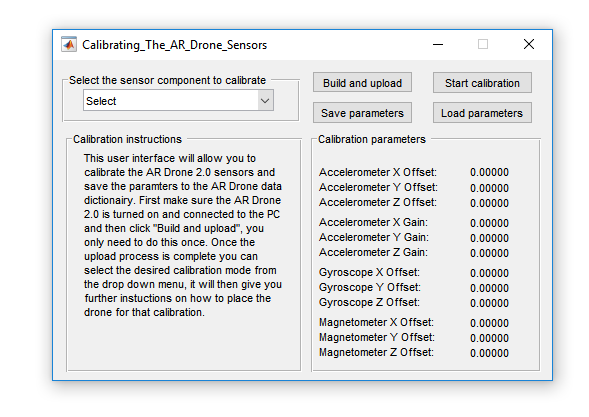

This GUI will allow you to calibrate the following parameters:

- **Accelerometer** **offset** **and** **gain: **This ensures that the gravity vector is measured as 1G pointing down when the drone is horizontal

- **Gyroscope** **offset: **The offset needs to be removed while the drone is stationairy so it does not wrongly believe it is moving

- **Magnetometer** **offset: **The base magnetometer offset is needed to determine the orientation of the drone. Note that none of the models in the toolbox make use of the magnetometer, you only need to calibrate it if you wish to make use of it yourself.

The calibration parameters are saved in the ArDroneDataDictionary such that they are available to any model linked to the dictionary. To learn more about how the data dictionary works please read the **Data Dictionaries **chapter in the **Concepts** section of this documentation. 

Pressing the **load parameters** button will load the values currently stored in the data dictionary. If you wish to restore these values to the default values you can do so by running the following script:

ResetCalibrationParameters

You can also run this script from the Simulink project shortcut: **Reset sensors to default**.

## Calibrating the sensors

Before you can calibrate the sensors you must first build the calibration model such that it is running on the AR Drone 2.0. 

    2.    Click the **Build and upload** button within the **Calibrating_The_Ar_Drone_Sensors **GUI after you have connected the AR Drone 2.0 to the Simulink PC. 

The **Calibrating_The_Ar_Drone_Sensors_Model **model will open as shown below. When the build process is complete the instructions text will update with new instructions.

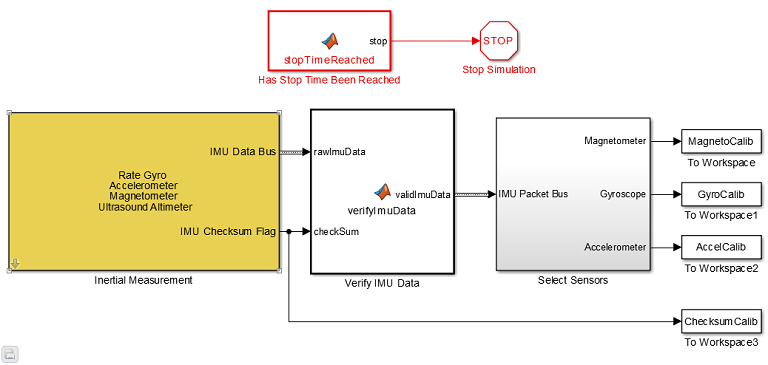

After the model has been build and uploaded to the AR Drone 2.0 you can perform calibrations. To run a calibration:

    4.    Select the desired calibration mode from the drop down menu

    5.    Follow the user instructions on how to position the AR Drone 2.0 for the calibration

    6.    Press the Start Calibration button to perform the calibration. Some calibration parameters require two calibrations in different modes.

# Model background

The model contains the following blocks:

- **Inertial** **Measurement**: This block is made using legacy Paparrazi C code which retrieves the inertial measurement unit data. It also outputs a checksum flag which indicates whether an IMU package was corrupted.

- **Verify IMU Data: **This block will hold IMU Data if the checksum failed untill a package is retrieved that passes the checksum flag and has a different checksum value.

- **Select sensors: **The data which we need for calibration is retrieved from the full IMU data inside this block.

- **Has Stop Time Been Reached: **The calibration GUI uses different calibration lengths for different calibration runs, they are passed from the GUI m file to this block such that it terminates after the desired time by calling the **Stop Simulation** block.

- **To Workspace:** These blocks will save the IMU data of interest to variables in the workspace which can then be read by the GUI m file.

## Accelerometer calibration:

The AR Drone 2.0 has three accelerometers, to calibrate them we need to run two calibration runs per sensor. The force of gravity acting on the Drone results in the fixed downpard acceleration of $9.81m/s^2$. By positioning the Drone such that the force of gravity exites only one accelerometer in the positive direction in one measurement, and in the negative direction in the second calibration measurement, we can determine the offset and gain for each accelerometer. Use the calibration selection dropdown menu to select one of the calibration modes and position the AR Drone 2.0 as explained in the user instructions. For a visual guide to positoning the AR Drone 2.0 during calibration see the **Calibration positioning **chapter. The default calibration parameters are:

- Accelerometer X,Y,Z offset = $2048$

- Accelerometer X,Y,Z Gain = $512$

## Gyroscope calibration:

The three gyroscopes have an offset that can be determined by averaging a measurement of the stationairy drone. The gyro offset should not be orientation dependent, to be safe we position the drone on its feet as this orientation resembles the orientation of the drone during flight the most. The default calibration parameters are:

- Gyroscope X,Y,Z offset = $0$

## Magnetometer calibration:

In order to find the magnetometer offset we have to find the maximum and minimum influence of earths magnetic field on the AR Drone 2.0. To do this the drone should be rotated around all three of its principle axes such that each of the three magnetometer sensors (X,Y,Z) experiences the maximum and minimum possible magnetic force. The default calibratoin parameters are:

- Magnetometer X,Y,Z offset = $0$